%productFlag = 0
productCounter = 0

productCounter = 0

%while productFlag == 0
    close all
    fig = uifigure;

    productCounter = productCounter+1;
    uilabel(fig, 'Text', 'Defining image products to generate:', 'FontSize', 24, 'Position', [30 375 500 50]);
    
    % Product Type
    uilabel(fig, 'Text', 'Product Label', 'FontSize', 16, 'Position', [50, 340, 300, 30]);
    product_type = uidropdown(fig, 'Items', {'cBathy', 'Timestacks', 'Other (fill in here)'}, 'Editable', 'on', 'Position', [50 310 200 30], 'FontSize', 16);

    % Frame Rate
    uilabel(fig, 'Text', 'Frame Rate (Hz)', 'FontSize', 16, 'Position', [50, 260, 300, 30]);
    frameRate_type = uieditfield(fig, "numeric", 'Position', [50 230 200 30], 'FontSize', 16, 'RoundFractionalValues', 'on', 'Limits', [1 30]);

    % dx
    uilabel(fig, 'Text', 'dx (m)', 'FontSize', 16, 'Position', [50, 180, 300, 30]);
    dx_type = uieditfield(fig, "numeric", 'Position', [50 150 200 30], 'FontSize', 16, 'RoundFractionalValues', 'off', 'Limits', [0.1 50]);

    % check if grid should be inputed or pulled from file
    bg = uibuttongroup(fig, 'Position', [50, 70, 200, 50]);
    rb1 = uiradiobutton(bg, 'Text', 'Use grid file.', 'Position', [10 30, 100, 15])

rb1 =   RadioButton (Use grid file.) with properties:

       Value: 1
        Text: 'Use grid file.'
    Position: [10 30 100 15]

  Show all properties


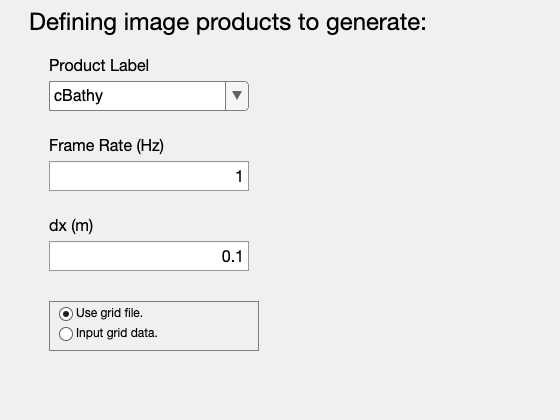

rb2 =   RadioButton (Input grid data.) with properties:

       Value: 0
        Text: 'Input grid data.'
    Position: [10 10 100 15]

  Show all properties


    rb2 = uiradiobutton(bg, 'Text', 'Input grid data.', 'Position', [10 10, 100, 15])



    fig.UserData = struct("Product_type", product_type, ...
                          "frameRate", frameRate_type, ...
                          "dx", dx_type, ...
                          "rb1", rb1, ...
                          "rb2", rb2)

    Product1.productType = fig.UserData.Product_type.Value;
    Product1.frameRate = fig.UserData.frameRate.Value;
    Product1.dx = fig.UserData.dx.Value;


    if rb2.Value == 1
        % Origin
        uilabel(fig, 'Text', 'Latitude (deg)', 'FontSize', 16, 'Position', [300, 260, 100, 30]);
        lat_type = uieditfield(fig, "numeric", 'Position', [300 230 100 30], 'FontSize', 16, 'RoundFractionalValues', 'off', 'Limits', [-90 90]);
        uilabel(fig, 'Text', 'Longitude (deg)', 'FontSize', 16, 'Position', [410, 260, 120, 30]);
        lon_type = uieditfield(fig, "numeric", 'Position', [410 230 100 30], 'FontSize', 16, 'RoundFractionalValues', 'off', 'Limits', [-180 180]);
        
        % Angle
        uilabel(fig, 'Text', 'Shorenormal angle of origin (CC degrees from North)', 'FontSize', 16, 'Position', [300, 180, 200, 50], 'WordWrap','on');
        angle_type = uieditfield(fig, "numeric", 'Position', [300 150 210 30], 'FontSize', 16, 'RoundFractionalValues', 'off', 'Limits', [0 360]);
    
        % Grid
        uilabel(fig, 'Text', 'Cross-shore Distance (m)', 'FontSize', 16, 'Position', [300, 100, 100, 50], 'WordWrap', 'on');
        crossshore_type = uieditfield(fig, "numeric", 'Position', [300 70 100 30], 'FontSize', 16, 'RoundFractionalValues', 'off', 'Limits', [0 2000]);
        uilabel(fig, 'Text', 'Alongshore Distance (m)', 'FontSize', 16, 'Position', [410, 100, 100, 50], 'WordWrap', 'on');
        alongshore_type = uieditfield(fig, "numeric", 'Position', [410 70 100 30], 'FontSize', 16, 'RoundFractionalValues', 'off', 'Limits', [0 2000]);
    else
        uiopen('*.mat')

    end

    % save data
    fig.UserData = struct("Product_type", product_type, ...
                          "frameRate", frameRate_type, ...
                          "dx", dx_type, ...
                          "Origin", origin_type, ...
                          "Angle", angle_type, ...
                          "grid", grid_type)

Unrecognized function or variable 'grid_type'.

    Product1 = 1

% set callback
%hButt.ButtonPushedFcn = @(src, event)increment(hEdit);d
%    eval(['Product.' product_type.Value '.productType = ' product_type.Value])
%    eval(['Product.' product_type.Value '.frameRate = ' char(string(frameRate_type.Value))])
%    eval(['Product.' product_type.Value '.dx = ' char(string(dx_type.Value))])




    % Products
    % answer2 = questdlg('Define more products?', 'Do you want to create more products?', 'Yes', 'No', 'Yes');
    % switch answer2
    %     case 'No'
    %         productFlag = 1;
    % end  

%end

    